# AMECH HW5

*Steven Henderson*

**Problem 1**

A periodic force F (t) has period T and is defined in the interval $-\frac{T}{2}$ ≤ t ≤ $\frac{T}{2}$ as


$$F\left(t\right)=F_0 \frac{2t}{T}$$


This is a periodic right-angle sawtooth, see the figure below. The force is driving a one-dimesional damped harmonic oscillator system


$$F\left(t\right)=\overset{\ldotp \ldotp }{\mathrm{mx}} +2m\gamma \overset{\ldotp }{x} +\mathrm{kx}$$


**(A) **Expand the force in Fourier series and give an expression for the nth term in the

expansion.


$$\begin{array}{l}
F\left(t\right)=\frac{A_0 }{2}+\sum_{n=1}^{\infty } \left\lbrack A_n \cos \left(\omega_n t\right)+B_n \sin \left(\omega_n t\right)\right\rbrack \\
A_n =\frac{2}{T}\int_{-\frac{T}{2}}^{\frac{T}{2}} F\left(t\right)\cos \left(\omega_n t\right)\textrm{dt},F\left(t\right)\;\textrm{is}\;\textrm{an}\;\textrm{odd}\;\textrm{function}\;\textrm{so}\;\textrm{odd}\;\textrm{times}\;\textrm{even}\;\textrm{is}\;\textrm{odd}\;\textrm{making},\\
A_n =0
\end{array}$$



$$\begin{array}{l}
B_n =\frac{2}{T}\int_{-\frac{T}{2}}^{\frac{T}{2}} F\left(t\right)\sin \left(\omega_n t\right)\mathrm{dt}=\frac{8}{T^2 }F_0 \int_0^{\frac{T}{2}} \mathrm{tsin}\left(\omega_n t\right)\mathrm{dt},\mathrm{integration}\;\mathrm{by}\;\mathrm{parts}\\
u=t,\mathrm{dv}=\sin \left(\omega_n t\right),\mathrm{du}=\mathrm{dt},v=-\frac{\cos \left(\omega_n t\right)}{\omega_n }\\
B_n =\frac{8}{T^2 }F_0 \left({}{\left\lbrack -\frac{\mathrm{tcos}\left(\omega_n t\right)}{\omega_n }\right\rbrack }^{\frac{T}{2}}_0+\frac{1}{\omega_n }\int_0^{\frac{T}{2}} \cos \left(\omega_n t\right)\mathrm{dt}\right)\\
B_n =8\frac{F_0 }{T^2 }\left(\left\lbrack -\frac{\mathrm{Tcos}\left(\omega_n \frac{T}{2}\right)}{2\omega_n }\right\rbrack +\frac{1}{\omega_n }{}{\left\lbrack \frac{\sin \left(\omega_n t\right)}{\omega_n }\right\rbrack }^{\frac{T}{2}}_0\right)\\
\omega_n =2\pi \frac{n}{T}
\end{array}$$



$$B_n =\frac{8F_0 }{T^2 }\left(-\frac{T^2 \cos \left(\pi n\right)}{4\pi n}+\frac{T^2 \sin \left(\pi n\right)}{4\pi^2 n^2 }\right)={\left(-1\right)}^{n+1} \frac{2F_0 }{\pi n}$$



$$F_n \left(t\right)={\left(-1\right)}^{n+1} \frac{2F_0 }{\pi n}\sin \left(\omega_n t\right)$$


**(B)** For mass m = 1 kg, T = 1 sec, and F`0` = 500 N, use MATLAB to plot the analytic

function of the force and overlay the force as calculated through the Fourier expansion

with n ≤ 5. Use the help provided below to plot the right angle sawtooth.

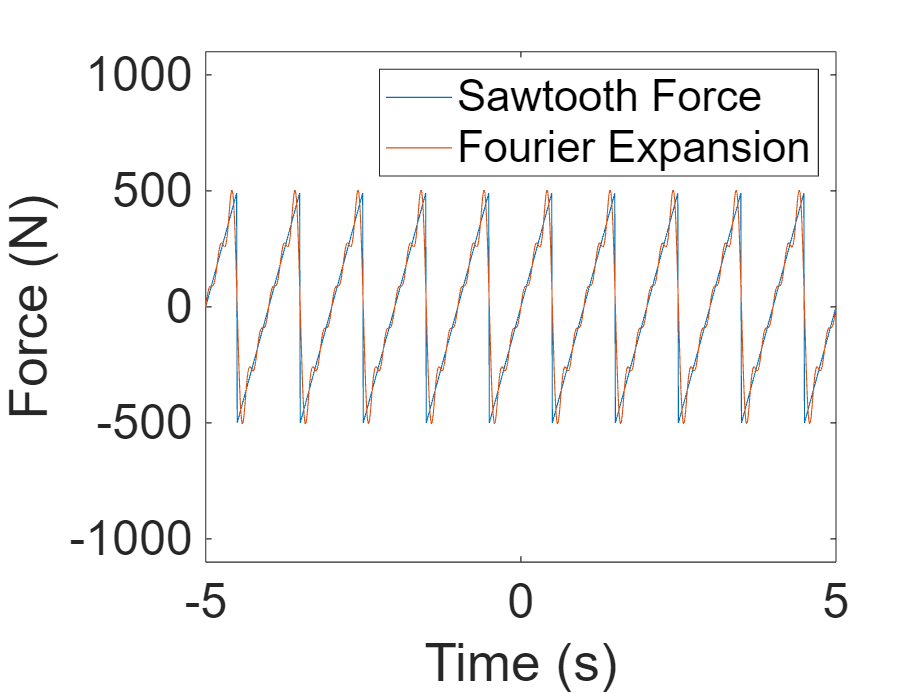

% Initial Variables
m = 1 ; % mass (kg)
T = 1 ; % period (s)
F_0 = 500 ; % initial force (N)
% Right Angle Sawtooth
time = -5:0.01:5 ; % s time array
A = 1000 ; % N/kg, mass normalized force constant peak-to-peak
period = 1 ; % sec, period of drive
Force = mod(A.*(time+period/2)./period,A) - A/2 ; % normalized force
% Loop 5 times over adding all terms to F
F = 0 ;
for n = 1:5
    F = F + (-1)^(n+1)*2*F_0/(pi*n).*sin(2*pi*n/T.*time) ; % Add up the Bn's
end
% Plot results
plot(time, Force)
hold on
plot(time, F)
xlabel('Time (s)')
ylabel('Force (N)')
set(gca, 'fontsize', 22)
legend('Sawtooth Force', 'Fourier Expansion')
ylim([-1100, 1100])
hold off

**(C) **In steady state, the displacement of the mass in response to this driving force (with n ≤ 5) is


$$x\left(t\right)=\sum_{n=1}^5 x_n \left(t\right)$$


In a single figure, plot each of the xi(t) assuming that the damping constant is γ = 0.75, and the natural frequency of the system is 60 rad/s.


$$\begin{array}{l}
\overset{\ldotp \ldotp }{x} +2\gamma \overset{\ldotp }{x} +\omega_0^2 x=F\left(t\right)\\
\left.\mathrm{Homogeneous}\;\mathrm{Solution}\;\left(f\left(t\right)=0\right)\right)\\
x_H \left(t\right)=\mathrm{Ccos}\left(\Omega t+\alpha \right)e^{-\gamma t} ,\mathrm{where}\;\Omega =\sqrt{\omega_0^2 =\gamma^2 }\\
\mathrm{For}\;\mathrm{steady}\;\mathrm{state},\mathrm{the}\;\mathrm{mass}\;\mathrm{must}\;\mathrm{oscillate}\;\mathrm{with}\;\mathrm{driving}\;\omega ,\\
\mathrm{try}\;x_n =\frac{f}{R}e^{i\omega_n t} ,\mathrm{where}\\
\frac{f}{R}\left\lbrack -{\omega_n }^2 +2i\gamma \omega_n +\omega_0^2 \right\rbrack e^{i\omega_n t} ={\mathrm{fe}}^{i\omega_n t} ,\mathrm{where}\;f=\frac{{2F}_0 }{\pi \mathrm{nm}}\\
\frac{1}{R}\left\lbrack -{\omega_n }^2 +2i\gamma \omega_n +\omega_0^2 \right\rbrack =1\\
\mathrm{where}\;\mathrm{Im}\left\lbrace \frac{f}{R}e^{i\omega_n t} \right\rbrace \;\mathrm{is}\;\mathrm{the}\;\mathrm{physical}\;\mathrm{solution}\\
R=\omega_0^2 -{\omega_n }^2 +2i\gamma \omega_n ={\mathrm{re}}^{i\theta_n } \\
r^2 ={\mathrm{RR}}^* ={\left({\omega_n }^2 -\omega_0^2 \right)}^2 +4\gamma^2 \omega_n^2 \\
\tan \theta_n =\frac{2\gamma \omega_n }{\omega_0 -{\omega_n }^2 }\\
x_n \left(t\right)=\mathrm{Im}\left\lbrack \frac{f}{r}e^{i\left(\omega t-\theta_n \right)} \right\rbrack =\frac{f}{r}\sin \left(\omega_n t-\theta_n \right)\\
\mathrm{Initial}\;\mathrm{conditions}\;\mathrm{do}\;\mathrm{not}\;\mathrm{matter}\;\mathrm{for}\;\mathrm{steady}\;\mathrm{state}\\
x_n \left(t\right)=\frac{B_n }{{\mathrm{mr}}_n }\sin \left(\omega_n t-\theta_n \right)
\end{array}$$


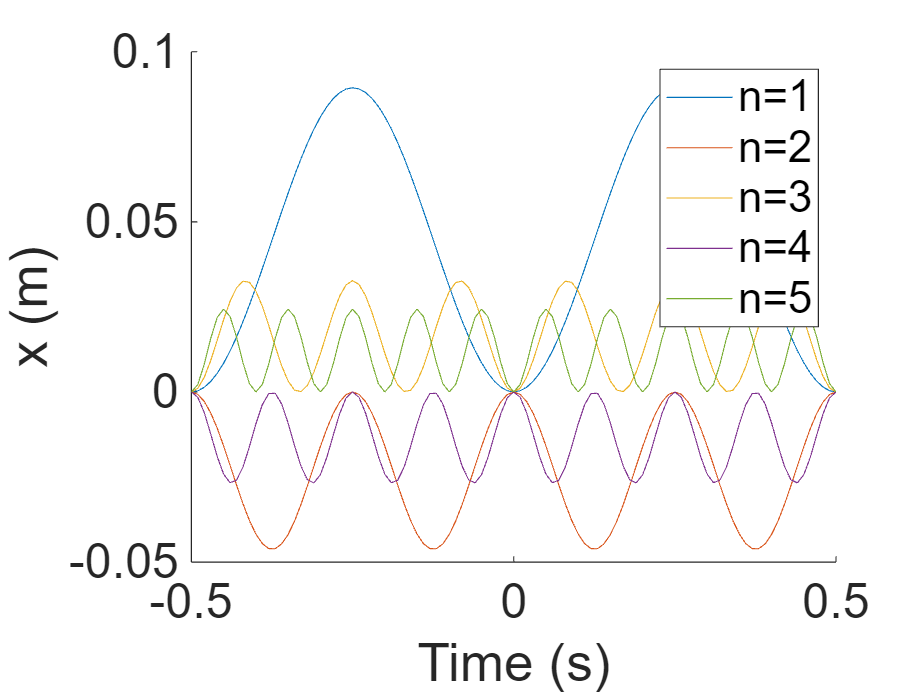

x_n = zeros(4, length(time)) ; % Initialize array for each x
omega_0 = 60 ; % natural frequency (rad/s)
gamma = 0.75 ; % damping constant
for n = 1:5 % Loop through and add each x to the array
    omega_n = 2*pi*n / T ; % driving frequency (rad/s)
    Bn = (-1)^(n+1)*2*F_0/(pi*n).*sin(2*pi*n/T.*time) ; % force contribution (N)
    theta =  atan((2*gamma*omega_n)/(omega_0^2-omega_n^2)); % phase difference (rad)
    rn = sqrt((omega_n^2 - omega_0^2)^2 + 4*gamma^2*omega_n^2) ; % r
    x_n(n, :) = (Bn/(rn*m)).*sin(omega_n.*time - theta) ; % add to x array using equation above
end
% Plot Results
clf
hold on
for i = 1:5
    plot(time, x_n(i, :))
end
xlabel('Time (s)')
ylabel('x (m)')
set(gca, 'fontsize', 22)
legend('n=1', 'n=2', 'n=3', 'n=4', 'n=5')
xlim([-0.5, 0.5])

(D) In an additional figure, plot the displacement of the mass x(t). Which of the harmonics contributes most for the displacement? Is any of the contributions much larger than he others, or are they all comparable? (Much larger would at least `×`10 larger than any other) What is the maximum displacement x? Does the displacement resemble the shape of the periodic force?

The first harmonic shows the largest contirbution as it is much larger but, in general they are all pretty comparable. The maxnmum displacement is around 0.15 and does not resemble the periodic force.

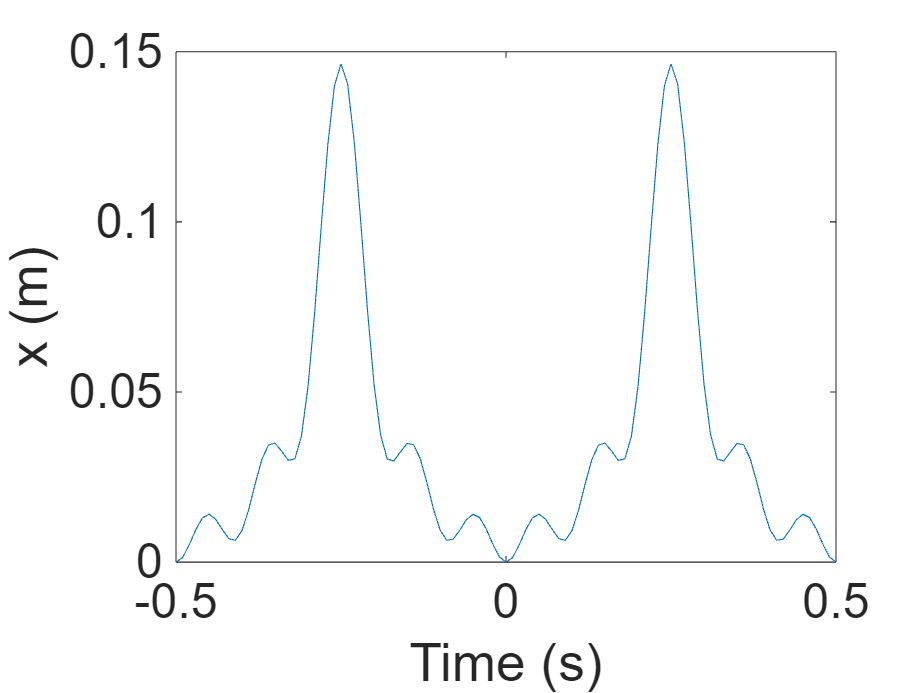

x_t = x_n(1, :)+x_n(2, :)+x_n(3, :)+x_n(4, :)+x_n(5, :) ;
clf
plot(time, x_t)
xlabel('Time (s)')
ylabel('x (m)')
set(gca, 'fontsize', 22)
xlim([-0.5, 0.5])

**(E) **Let’s suppose the natural frequency of the system is 19 rad/s. Rerun your code with

the new natural frequency. Show the figure with xi and the one for x for this case as

well. (You can save plots and attach them to the text portion of the .mlx.) Which of

the harmonics contributes most for the displacement now? Are they all comparable?

What is the maximum displacement x? Does the displacement resemble the shape of

the periodic force?

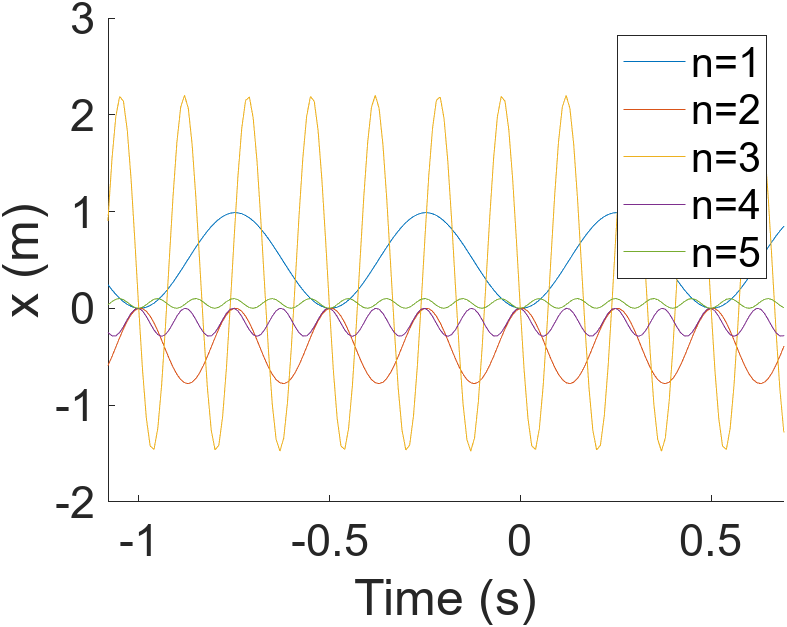

n = 3 contribute most to the displacement and each harmonic has a substaintially different amplutude with some not contributing as much as others.

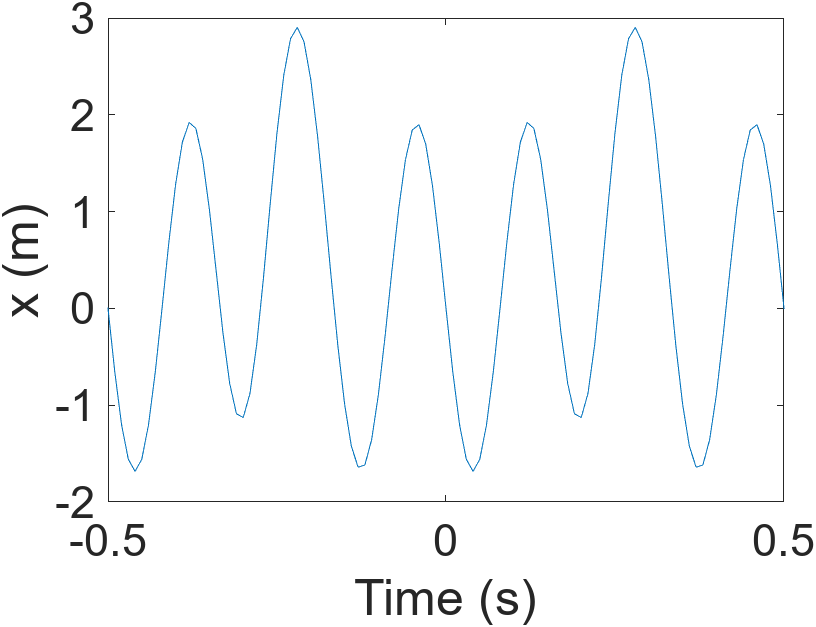

The max displacment is about 3 and does not coorelate with the periodic force.

**(F) **Why is x(t) larger when the natural frequency is 19 Hz than when it is 60 Hz?

It is because it is closer to the resonant frequency.

**Problem 2**

Understanding the behavior of the CO`2` molecule is critical for understanding climate change. The molecule is co-linear with the oxygen atoms bracketing a central carbon atom, all along a straight line (see, for example, wikipedia). The connections between the atoms can be considered springs, making a system of three masses connected with two equal springs. Wewill only consider 1-dimensional motions along the line connecting the atoms. (The moleculedoes ’bend’ as well, a mode that is also important for climate change. ) Set useful coordinates and solve for the general motion of the molecule.

**(A)** Find the Lagrangian.


$$\begin{array}{l}
V=\frac{1}{2}\left\lbrack k_1 {\left(x_1 -x_2 \right)}^2 +k_2 {\left(x_2 -x_3 \right)}^2 \right\rbrack ,\textrm{where}\;x_{n\;} \textrm{is}\;\textrm{the}\;\textrm{displacement}\;\textrm{of}\;\textrm{the}\;\textrm{mass}\\
K=\frac{1}{2}\left(m_1 v_1^2 +m_2 v_2^2 +m_3^2 \right)\\
L=\frac{1}{2}\left(m_1 v_1^2 +m_2 v_2^2 +m_3^2 \right)-\frac{1}{2}\left\lbrack k_1 {\left(x_1 -x_2 \right)}^2 +k_2 {\left(x_2 -x_3 \right)}^2 \right\rbrack 
\end{array}$$



$$\begin{array}{l}
\frac{\partial L}{\partial x_1 }=-k_1 \left(x_1 -x_2 \right)\\
\frac{\partial L}{\partial x_2 }={-k}_1 \left(x_2 -x_1 \right)-k_2 \left(x_2 -x_3 \right)\\
\frac{\partial L}{\partial x_3 }={-k}_2 \left(x_3 -x_2 \right)\\
\frac{d}{\mathrm{dt}}\left(\frac{\partial L}{\partial {\overset{\ldotp }{x} }_1 }\right)=m_1 \overset{\ldotp \ldotp }{x_1 } \\
\frac{d}{\mathrm{dt}}\left(\frac{\partial L}{\partial {\overset{\ldotp }{x} }_2 }\right)=m_2 \overset{\ldotp \ldotp }{x_2 } \\
\frac{d}{\mathrm{dt}}\left(\frac{\partial L}{\partial {\overset{\ldotp }{x} }_3 }\right)=m_3 \overset{\ldotp \ldotp }{x_3 } 
\end{array}$$


**(B)** Formulate the equations of motion in matrix form and use MATLAB to find the normal frequencies and normal modes assuming the known masses of the atoms and k = 840 N/m.